# Urban Channel Link Analysis and Visualization using Ray Tracing

This example shows how to use ray tracing to analyze a communication link in an urban environment. Buildings data is imported into Site Viewer from an OpenStreetMap file corresponding to Hong Kong. Transmitter and receiver sites are placed in the city, and ray tracing is used to plot multiple propagation paths. The ray tracing results are recorded from Site Viewer and used to define a channel model for filtering a signal.

## Import and Visualize Buildings Data

Import an OpenStreetMap (.osm) file corresponding to Hong Kong. The file was downloaded from [https://www.openstreetmap.org](https://www.openstreetmap.org/), which provides access to crowd-sourced map data all over the world. The buildings information contained within the OpenStreetMap file is imported and visualized in Site Viewer.

viewer = siteviewer("Buildings","hongkong.osm");

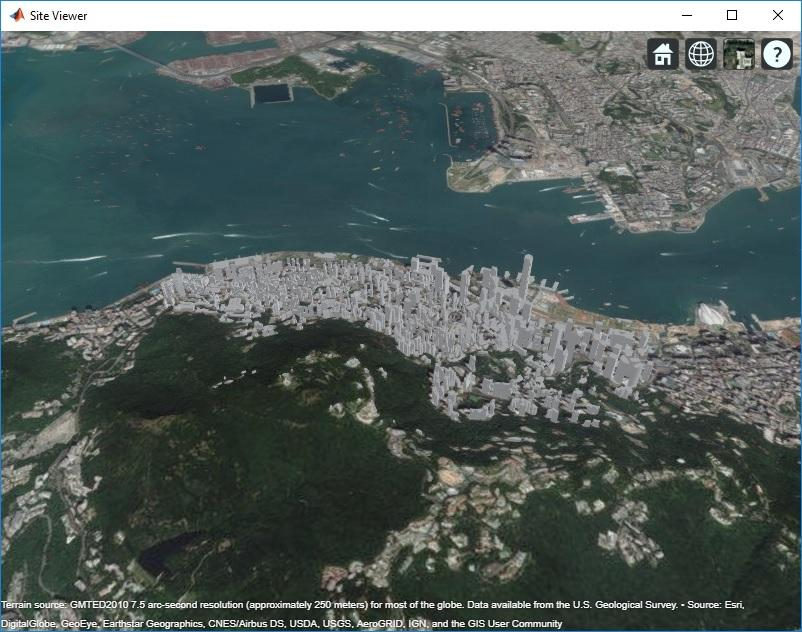

Zoom and rotate the map to view the buildings and terrain.

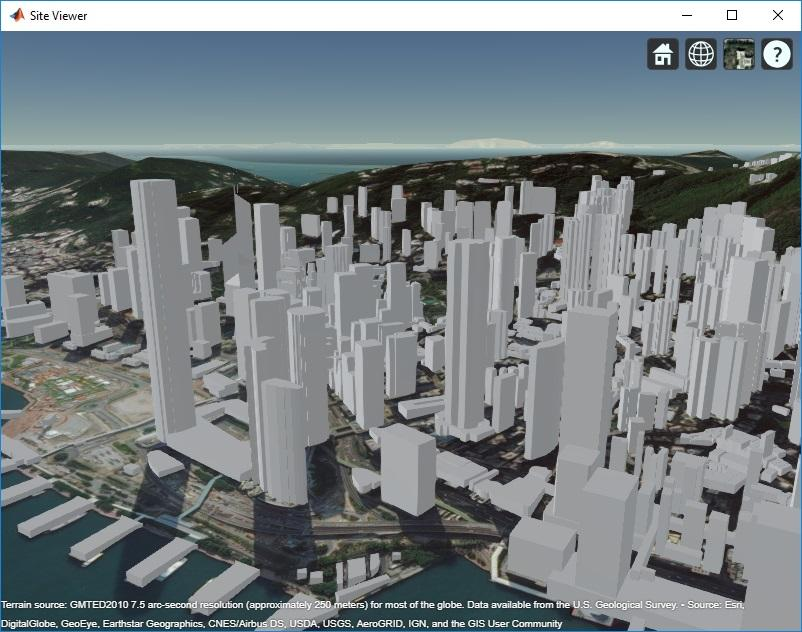

## Define Transmitter and Receiver Sites

Define transmitter and receiver sites to model a small cell scenario in a dense urban environment. The transmitter site represents a base station that is placed on a pole near a road, and the receiver site is placed along a road. The transmitter operates at a carrier frequency of 28 GHz with 5 W of power. The transmitter and receiver sites use a default isotropic antenna, which radiates uniformly in all directions.

tx = txsite("Name","Small cell transmitter", ...
    "Latitude",22.2789, ...
    "Longitude",114.1625, ...
    "AntennaHeight",10, ...
    "TransmitterPower",5, ...
    "TransmitterFrequency",28e9);

rx = rxsite("Name","Small cell receiver", ...
    "Latitude",22.2799, ...
    "Longitude",114.1617, ...
    "AntennaHeight",1);

## Plot Propagation Paths using Ray Tracing

Plot propagation paths between the transmitter and receiver sites, including paths with up to two reflections. The propagation paths are computed using ray tracing analysis, which considers the buildings and terrain geometry around the sites to determine line-of-sight or reflected paths. Each path may be selected to view the corresponding propagation characteristics, including path loss, phase change, distance, and angles of departure and arrival.

raytrace(tx,rx,"NumReflections",[0 1 2], ...
    "Type","pathloss", ...
    "ColorLimits",[80 130])

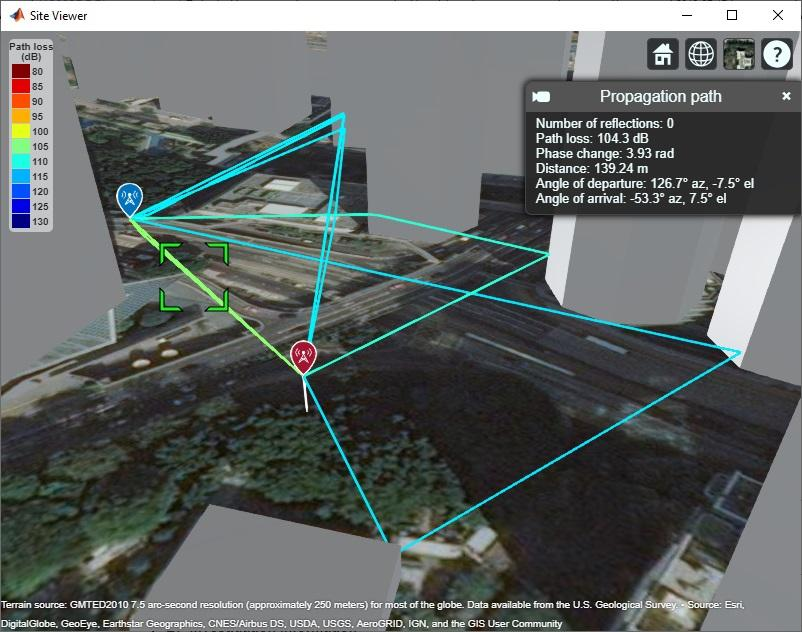

## Define Multipath Channel Model using Ray Tracing

The path loss and distance of each propagation path are recorded from Site Viewer. The seven paths from the transmitter to the receiver result in a multipath channel. The path gains and delays for the channel are derived from the ray tracing results. A plot of the channel impulse response shows that the paths arrive in four clusters.

% Record ray tracing results, which must be obtained by selecting each path
% in Site Viewer and reading the values from the infobox. Below, the values
% are sorted according to corresponding path distance.
pathDists  = [139.24 139.38 249.01 339.57 339.81 340.68 356.98]; % Unit: meter
pathLosses = [104.3 104.3 109.3 112 112 112 112.4];              % Unit: dB
pathPhases = [3.93 5.95 1.46 2.73 5.67 3.27 5.83];               % Unit: radians

% Derive the complex gain and time of arrival for each path
pathGains = 10.^((-1*pathLosses)/20) .* exp(1i*pathPhases);
pathToA = pathDists/physconst("lightspeed"); % Unit: second

% Plot channel impulse response
stem(pathToA-min(pathToA), abs(pathGains), 'filled');
grid on;
title('Channel Impulse Response');
xlabel('Delay (s)'); ylabel('Magnitude'); 

A signal is passed through the channel and plotted in a constellation diagram. In order to model the effects of a receiver in motion, an instantaneous speed is defined which produces a Doppler frequency shift. The received signal is highly distorted due to the significant intersymbol interference (ISI) caused by the multipath channel on a wideband 5G signal.

% Define instantaneous receiver speed and derive Doppler shift
rxSpeed = 2; % Unit: m/s
fd = rxSpeed * tx.TransmitterFrequency / physconst("lightspeed");

% Set the sampling rate, frame length and constellation size
Rs = 122.88e6; % Corresponds to 5G signal rate
frmLen = 30720;
M = 64;
constDiagram = comm.ConstellationDiagram( ...
    "XLimits",[-15 15], ...
    "YLimits",[-15 15], ...
    "ReferenceConstellation",qammod(0:M-1, M));

% Randomly generate 64-QAM signals to be passed through the channel. 
% Perform channel filtering and observe the channel-impaired signal in
% the constellation diagram. The path gains are normalized in order to
% preserve the average input signal power. 
data  = randi([0 M-1], frmLen, 1);
txSig = qammod(data, M);
rxSig = helperRayTracingChannelModel(Rs, pathToA, txSig, pathGains/norm(pathGains), fd);
constDiagram(rxSig);

## Plot Propagation Paths with Multiple Receiver Sites

The previous ray tracing analysis was performed between a transmitter and receiver site with line-of-sight visibility. Now add two new sites that do not have line-of-sight visibility. The los plot reveals the obstruction points between sites.

rx2 = rxsite("Latitude",22.279755,"Longitude",114.161308);
rx3 = rxsite("Latitude",22.280087,"Longitude",114.160709);
rxs = [rx rx2 rx3];
los(tx,rxs)

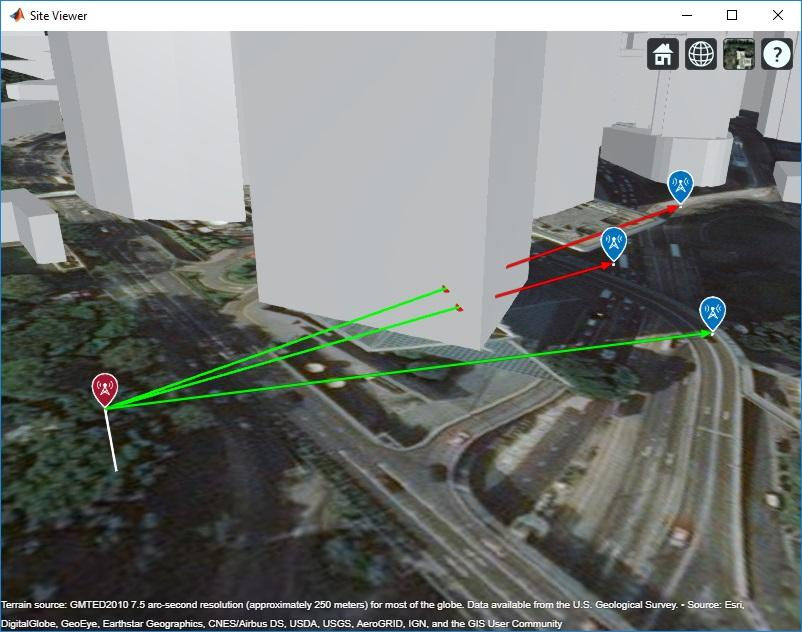

Although no line of sight exists, ray tracing analysis may reveal potential propagation paths for the communication link. For this scenario, use the default number of reflections to limit propagation paths to line-of-sight or single-bounce paths, and plot received power along each path.

The ray tracing analysis reveals that a reflected propagation path reaches one of the new receiver sites but not the other. The received power along the reflected path is -76.6 dBm.

% Show isotropic radiation pattern. Other antenna patterns can be used
% in conjunction with Antenna Toolbox or Phased Array System Toolbox.
pattern(tx,"Size",25)

% Plot propagation paths
raytrace(tx,rxs,"ColorLimits",[-100 -40])

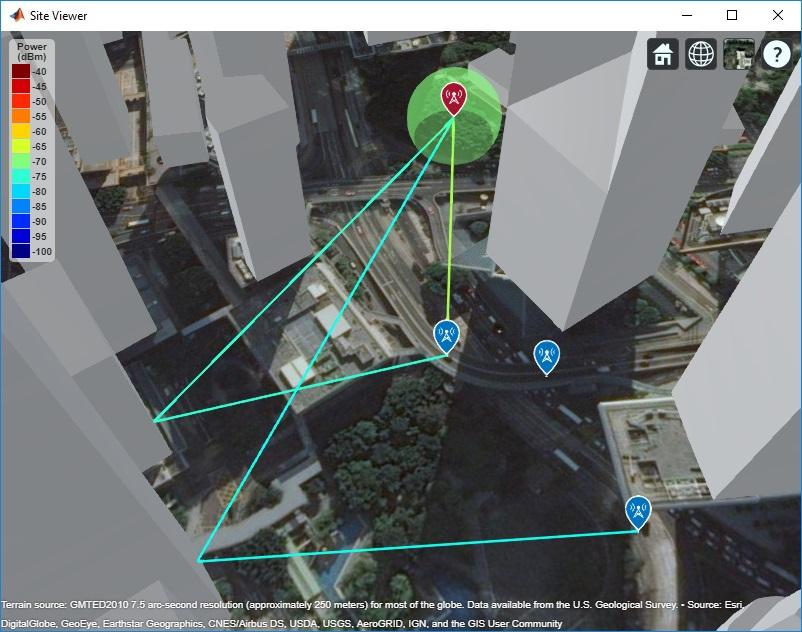

*Copyright 2019 The MathWorks, Inc.*